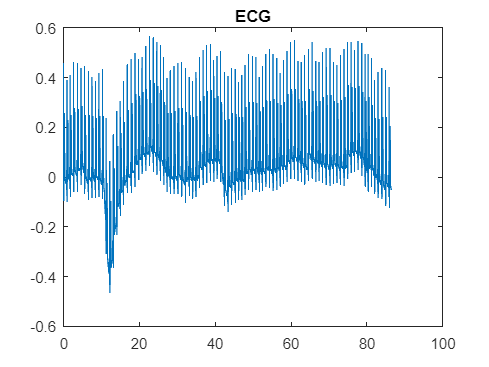

%%
% 
%  PREFORMATTED
%  TEXT
% 
% CW2 Tutorial
load ('C:\Users\dabst\OneDrive\Desktop\signals\Data\Data\1\1-AP.mat')
% for example, in this case, I choose 
%1. channel 5 ECG
myECG = b(:,5);
%2. channel 2 PCG
myPCG = b(:,2);
%3. channel 4 or 9 respiratory
respSig1 = b(:,4);
respSig2 = b(:,9);
myTime = b(:,1);
Fs = 20000; 
% Visualise
 plot(myTime,myECG), title('ECG')

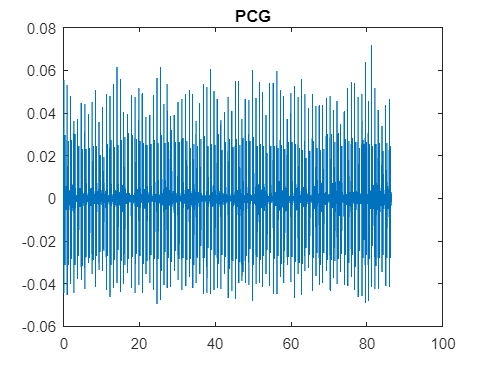

 plot(myTime,myPCG), title('PCG')

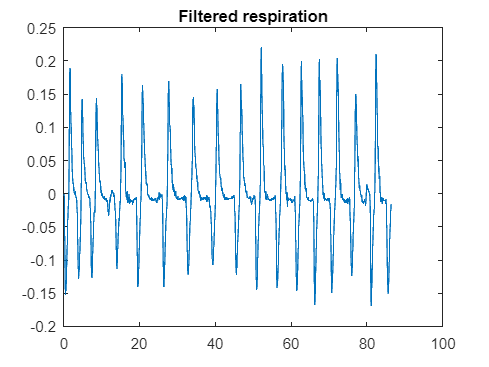

 plot(myTime,respSig2), title('Filtered respiration')

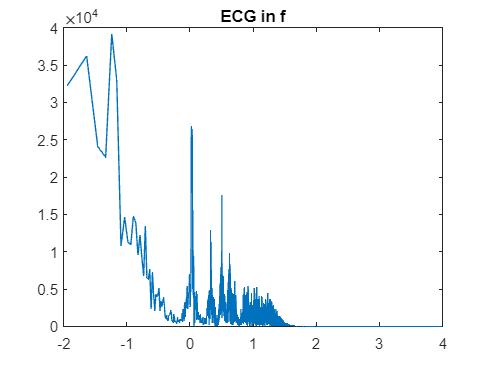

%finding cut off frequency of ECG
L = length(myECG);
f = Fs*(0:(L/2))/L;
ecgFFT = fft(myECG);
if mod(L,2) == 1
    L= L+1;
end 
ecgPower = abs(ecgFFT(1:L/2));
totalpower_ecg=sum(ecgPower);
plot(log10(f(1:L/2)),ecgPower),title("ECG in f")

energy=0

energy = 0

for i= 1:length(f)
    energy=energy+ecgPower(i);
    if energy>=0.5*totalpower_ecg
        cutoff=f(i)
        break
    end
end

cutoff = 11.4279


%finding bandwidth
energy=0

energy = 0

for i= 1:length(f)
    energy=energy+ecgPower(i);
    if energy>=0.95*totalpower_ecg
        bandwidth=f(i)
        break
    end
end

bandwidth = 1.8054e+03

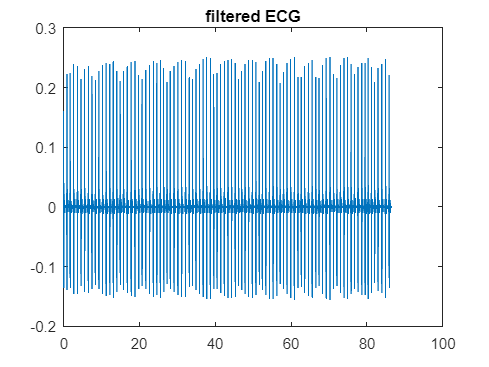



% high pass filter
[b,a] = butter(3,cutoff/(Fs/2),'high');
myECG = filtfilt(b,a,myECG);

plot(myTime,myECG), title('filtered ECG')

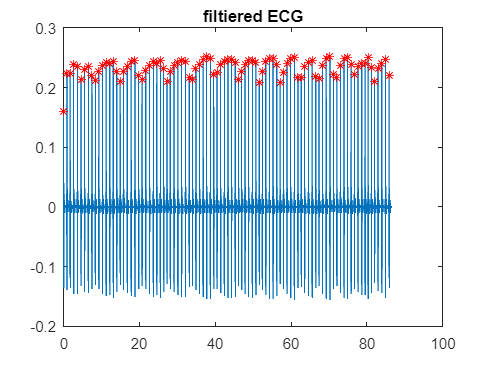

%plot(myTime,myPCG), title('filtered PCG')


%[pks,locs] = findpeaks(myECG);
% plot(myTime,myECG), title('filtered ECG')
%hold on
%plot(myTime(locs),pks,'r*')
%hold off
% add parameter
% Find peaks (one of the many methods)
[pks1,locs1] = findpeaks(myECG, Fs, 'MinPeakHeight',0.15);
plot(myTime,myECG) 
hold on
plot(locs1,pks1,'r*'),title('filtiered ECG')

hold off

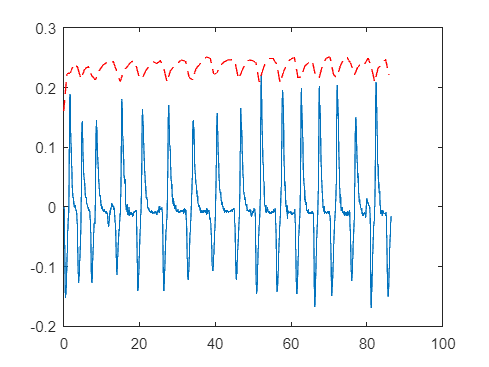

plot(myTime,respSig2)
hold on
plot(locs1,pks1,'r--')


% Using correlation
% N = round(length(respSig2)/length(locs1))
% ECGpeaks = interp(pks1,N);
% corrcoef(respSig2,ECGpeaks(1:length(respSig2)))
%using peak count
close all
newfs = length(pks1)/max(myTime) %new sampling frequency is length of peaks from ecg over time

newfs = 1.0746

[pks2,locs2] = findpeaks(pks1,newfs, 'MinPeakDistance',3);
plot(locs1,pks1)
hold on
plot(locs2,pks2,'*k')
ecgRate = 60*length(pks2)/max(myTime)

ecgRate = 11.0928

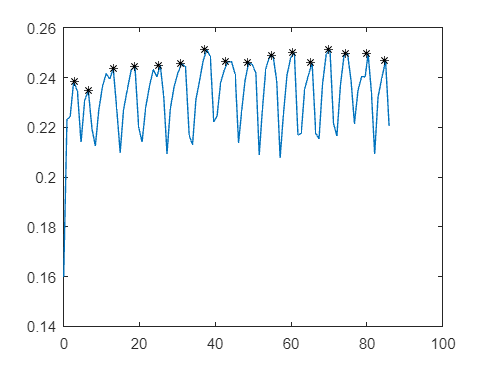


hold off


% peaks of respiration 
[pks3,locs3] = findpeaks(respSig2,Fs, 'MinPeakDistance',3);
plot(myTime,respSig2)
hold on
plot(locs3,pks3,'*k')
trueRate = 60*length(pks3)/max(myTime)

trueRate = 14.5593


Error = abs(ecgRate-trueRate)

Error = 3.4665

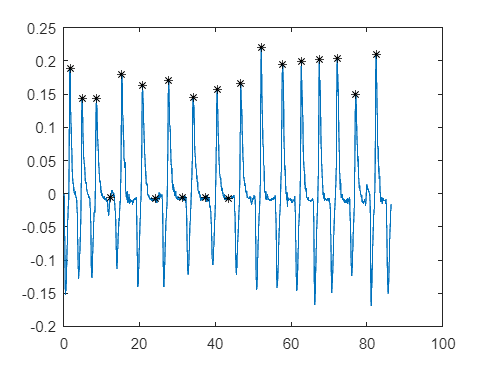

hold off

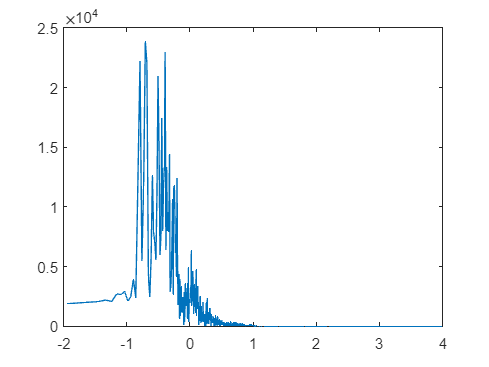

% What about the frequency
% What is the spectrum of respiration
L = length(respSig2);
f = Fs*(0:(L/2))/L;
respFFT = fft(respSig2);
if mod(L,2) == 1
    L= L+1;
end 
Px = abs(respFFT(1:L/2));
plot(log10(f(1:L/2)),Px)


% mean frequency
mn = meanfreq(respSig2,Fs);
freqrate = mn*60 % does this look correct to you?

freqrate = 24.8100

md = medfreq(respSig2,Fs);
freqrate2 = md*60 % does this look correct to you?

freqrate2 = 21.2503

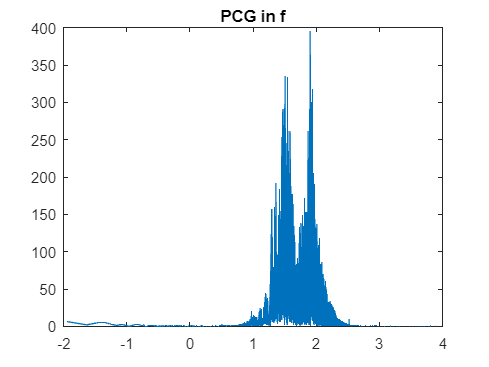



%PCG Conversion
L_p = length(myPCG);
f_p = Fs*(0:(L_p/2))/L_p;
pcgFFT = fft(myPCG);
if mod(L_p,2) == 1
    L_p= L_p+1;
end 
pcgPower = abs(pcgFFT(1:L_p/2));
totalpower_pcg=sum(pcgPower);
plot(log10(f_p(1:L/2)),pcgPower),title("PCG in f")


% finding 95% percintlile and 5 percintile frequency therb
% energy=0;
% low_end=0;
% high_end=0;
% for x=1:(length(f_p)-1)
%     energy=energy+pcgPower(x);
%     if energy>=0.05*totalpower_pcg
%         low_end=f_p(x);
%     end
% end
% energy=0;
% for y=1:(length(f_p)-1)
%      energy=energy+pcgPower(y);
%     if energy>=0.95*totalpower_pcg
%         high_end=f_p(y);
%     end
% end
Cp=cumsum(pcgPower)

Cp = 1.0e+05 *

    0.0005
    0.0006
    0.0006
    0.0007
    0.0007
    0.0008
    0.0008
    0.0008
    0.0008
    0.0008


f_ind= (Cp>0.05*totalpower_pcg) &(Cp<0.9*totalpower_pcg)

f_ind = 865427×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


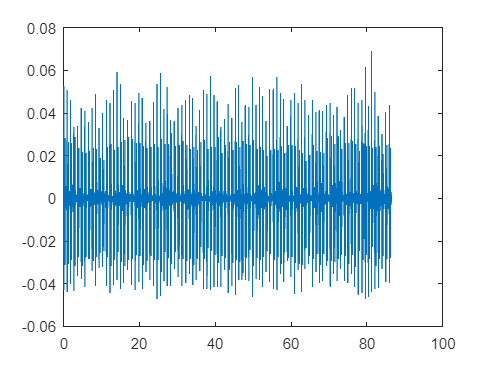

low_end=min(f_p(f_ind));
high_end=max(f_p(f_ind));
%hold on
%[peak_pcg,loc]=findpeaks(pcgPower,f_p(1:length(pcgPower)),'MinPeakHeight',395);
%plot(log10(loc),peak_pcg,'r*');
%hold off
%cutoff=loc;
a = bandpass(myPCG,[low_end high_end],Fs);
plot(myTime,a);

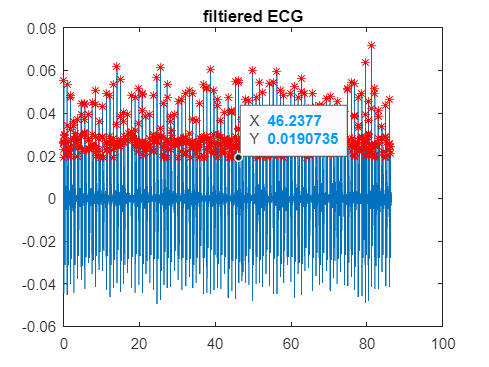


[pks1,locs1] = findpeaks(myPCG, Fs, 'MinPeakHeight',0.019);% Find peaks (one of the many methods)
plot(myTime,myPCG) 
hold on 
plot(locs1,pks1,'r*'),title('filtiered ECG')

hold off

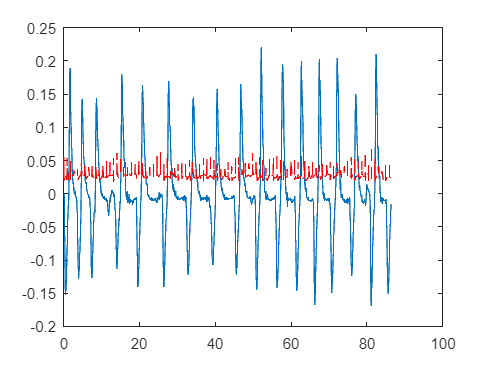

plot(myTime,respSig2)
hold on
plot(locs1,pks1,'r--')
hold off

newfs = length(pks1)/max(myTime) %new sampling frequency is length of peaks from ecg over time

newfs = 11.1968

[pks2,locs2] = findpeaks(pks1,newfs, 'MinPeakDistance',3);
plot(locs1,pks1)
hold on
plot(locs2,pks2,'*k')
pcgRate = 60*length(pks2)/max(myTime)

pcgRate = 15.2526

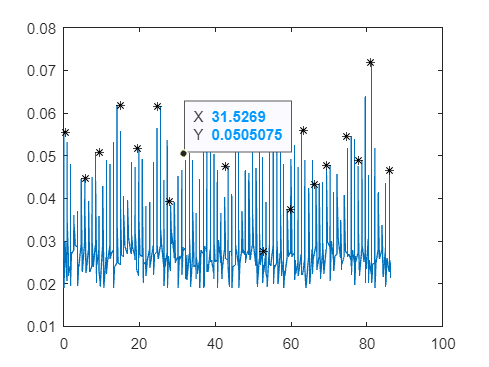


hold off

%Bandwidth of PCG
energy=0

energy = 0

for i= 1:length(f_p)
    energy=energy+pcgPower(i);
    if energy>=0.95*totalpower_pcg
        bandwidth_pcg=f_p(i)
        break
    end
end

bandwidth_pcg = 6.6308e+03